计算具有时变谐振频率的超表面的能带结构

创建者：FTT

创建时间：2024.12.12

clear
clc
close all

表面电容和表面电感

C0 = 0.1e-12;
L0 = 1e-9;

常量

eps0 = 8.854*1e-12; %真空介电常数
mu0 = 4*pi*1e-7; %真空磁导率
c0 = 1/sqrt(eps0*mu0); %真空光速

定义参数

omega_r0 = 1/sqrt(C0*L0); %归一化谐振频率
omega_m = 2* omega_r0; %调制频率
m = 0.2; %调制强度
k_r0 = omega_r0/c0; %归一化波数

定义计算范围

krange = linspace(0.01,20,1000)*k_r0;
N = 1; %展开阶数，形成2N+1阶的矩阵
omegarange = linspace(0, omega_m, 1000); %解弗洛奎频率范围（实部）
imomegarange = 0.5*omega_m+1i*linspace(-0.2, 0.2, 1000)*omega_m; %解弗洛奎频率范围（虚部）
Range = 1:length(omegarange);
tor = omega_m/500; %认为是带隙的容差
omeganum = 4; %限制最多保存的解的个数
ReErrorMartix = zeros(length(krange), length(omegarange)); %行列式矩阵（计算实部）
ImErrorMartix = zeros(length(krange), length(omegarange)); %行列式矩阵（计算虚部）

扫k，然后代入每个频率求行列式值（实部）

for ki = 1:length(krange)

构造谐波系数矩阵

    M = zeros(2*N+1, 2*N+1, length(omegarange));
    for i = 1:2*N+1
        for j = 1:2*N+1
            n = i - (N+1); %级次
            omega_n = @(n) omegarange+n*omega_m; %谐波频率
            alpha_n = sqrt(krange(ki)^2-omega_n(n).^2*eps0*mu0);
            if i == j %主对角线
                Y_n = 1i*omega_n(n)*C0+1./(1i*omega_n(n)*L0);
                M(i, j, :) = Y_n.*alpha_n + 1i*omega_n(n)*eps0;
            elseif i - j == 1 %下次对角线
                M(i, j, :) = 1i*omega_n(n)*m/2*C0.*alpha_n;
            elseif i - j == -1 %上次对角线
                M(i, j, :) = 1i*omega_n(n)*m/2*C0.*alpha_n;
            end
        end
    end
    for g = 1:length(omegarange)
        ReErrorMartix(ki, g) = 1/abs(det(M(:, :, g)));
    end

    % 代入带隙内频率 \omega = 0.5\omega_m+i\Im(\omega)
    M = zeros(2*N+1, 2*N+1, length(omegarange));
    for i = 1:2*N+1
        for j = 1:2*N+1
            n = i - (N+1); %级次
            omega_n = @(n) imomegarange+n*omega_m; %谐波频率
            alpha_n = sqrt(krange(ki)^2-omega_n(n).^2*eps0*mu0);
            if i == j %主对角线
                Y_n = 1i*omega_n(n)*C0+1./(1i*omega_n(n)*L0);
                M(i, j, :) = Y_n.*alpha_n + 1i*omega_n(n)*eps0;
            elseif i - j == 1 %下次对角线
                M(i, j, :) = 1i*omega_n(n)*m/2*C0.*alpha_n;
            elseif i - j == -1 %上次对角线
                M(i, j, :) = 1i*omega_n(n)*m/2*C0.*alpha_n;
            end
        end
    end
    for g = 1:length(omegarange)
        ImErrorMartix(ki, g) = 1/abs(det(M(:, :, g)));
    end
end

绘制颜色图

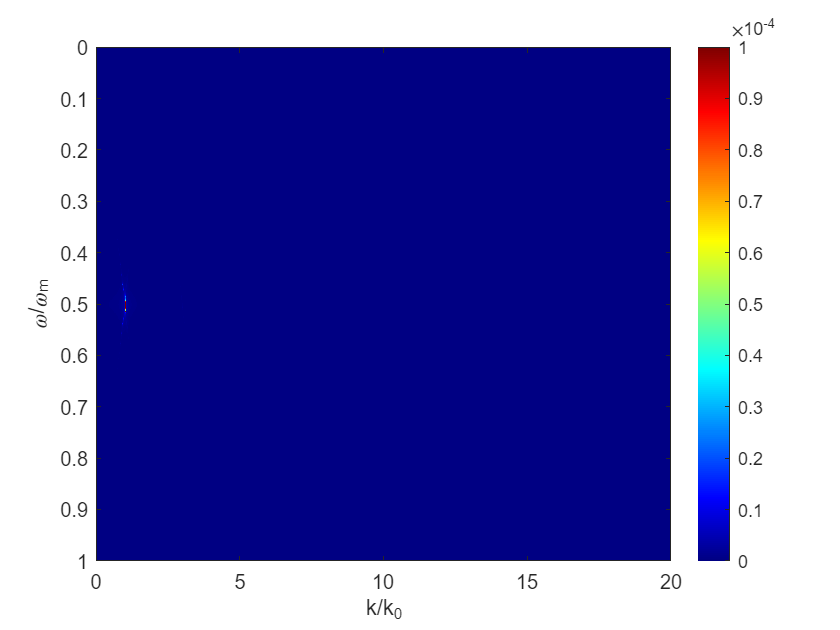

figure;
imagesc(krange/k_r0, linspace(0, omega_m, 1000)/omega_m, ReErrorMartix')
colormap('jet')
clim([0 0.0001])
colorbar;
xlabel('k/k_r_0')
ylabel('\omega/\omega_m')

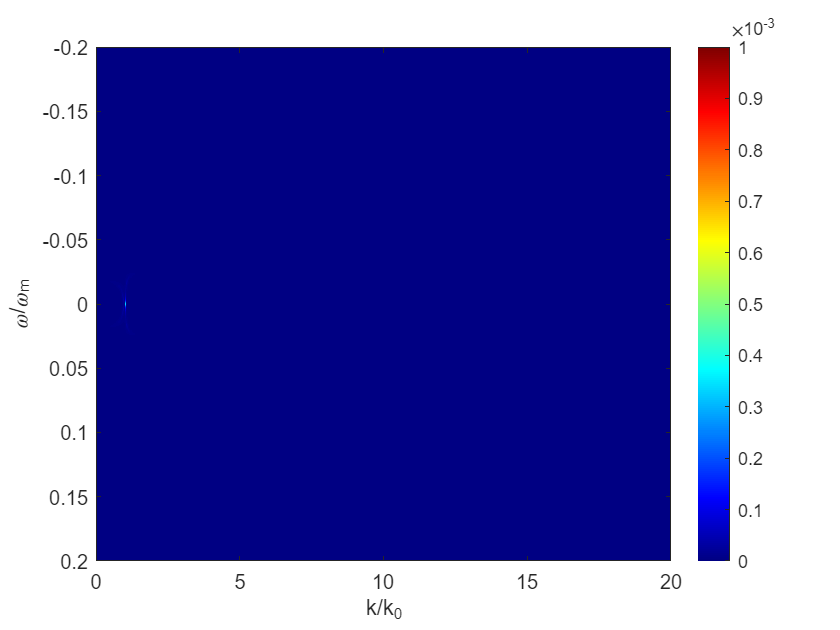


figure;
imagesc(krange/k_r0, linspace(-0.2, 0.2, 1000), ImErrorMartix')
colormap('jet')
clim([0 0.001])
colorbar;
xlabel('k/k_r_0')
ylabel('\omega/\omega_m')